# Simulation von Traktionsfahrten und Auslegung von Traktionsbatterien für den Bahnverkehr

## Laden von Notwendigen Daten:

Die Daten können auch angepasst werden, wenn zum Beispiel ein neuer Fahrplan, ein weiteres Fahrzeug oder eine neue Strecke hinzugefügt werden sollen. Auch können konstanten oder Fahrzeugparameter im betreffenden File angepasst werden.

% Fahrplan wird eingelesen. Bei dem hinterlegten Fahrplan handelt es sich
% um einen typischen Montag im Jahr 2022. Die Verbindungen zu den
% Hauptverkehrszeiten (06:00 - 09:00 Uhr und 16:00 - 19:00 Uhr) sind im
% Fahrplan eingetragen.
Import_timetable;

% Es wurde ebenfalls ein Fahplan für einen Sonntag hinterlegt. Dieser kann
% ebenfalls verwendet werden:
% Import_timetableSunday;
% Timetable = TimetableSunday;

% Fahrzeugparameter werden vom Skript Fahrzeugparameter.mlx eingelesen. In
% diesem Skript können weitere Fahrzeugmodelle hinterlegt werden. Es müssen
% dieselben Einheiten verwendet werden wie bei den vorgegebenen Modellen
% KISS und RE450.
Fahrzeugparameter;  

% Streckendaten aus ZLR Daten werden importiert.
Import_track_ZLR_Data; 

% Die Streckendaten können ebenfalls aus einer json-Datei importiert
% werden. Dazu muss das folgende Skript verwendet werden:
% Import_track_json_data;

% Laden der Messungen von SBB (8 min Mittelwerte)
Import_measurements2; 

% Wenn nicht anders angegeben wird immer das festgesetzte Fahrzeug auf den
% festgelegten Strecken und mit dem vorgegebenen Fahrplan simuliert. Falls
% dies anderst gemacht werden soll, müssen die einzulesenden Daten
% (Strecke, Fahrzeuge etc.) angepasst/erweitert werden.

% Nachfolgend muss angegeben werden, ob die Simulation die Fahrtzeit im
% Fahrplan einhalten, oder die Strecke so schnell wie möglich zurücklegen
% soll:
SimulationsMethode = "SpeedOptimized"; % "TimeTableOptimized";

% Die Fahrzeugparameter können auch in einem anderen Format importiert
% werden. Falls z.Bsp. ein Json-File mit den Daten des Fahrzeuges
% hinterlegt werden soll, kann das Skript "Fahrzeugparameter_parsing.mlx"
% verwendet werden.
% Fahrzeugparameter_parsing;

% Eingabe des gewünschten Fahrzeugtypes für die Berechnungen. Die
% gewünschte Komposition des Fahrzeuges während der Fahrt muss im Skript
% "Fahrzeugparameter" angepasst werden.
% Bereits vorhandene Fahrzeuge: KISS, RE450
FZ = input('Geben Sie den gewünschten Fahrzeugtypen für die Simulation ein: ');

## Simulation aller Strecken mit allen Fahrtzeiten: (TrackSimTime)

Es werden alle im Fahrplan festgelegten einzigartigen Verbindungen (Strecke und Fahrtzeit) zunächst einmal simuliert. Dies muss gemacht werden, da spätere Berechnungen mit diesen Simulationsergebnissen arbeiten.

% Die Simulationsergebnisse werden alle in einem Struct gespeichert und
% können später weiter gebraucht werden.

SimStreckenU = TrackSimTime(Strecken, Timetable, const, FZ, SimulationsMethode);

## Berechnung des Fahrplanes: (FahrplanSim)

Die vorher durchgeführte Berechnung aller variationen der Strecken ermöglicht es nun, den gesamten hinterlegten Fahrplan zu simulieren. Dabei wird der Fahrplan Fahrt um Fahrt durchgegangen und die entsprechende, vorher berechnete Strecke hinterlegt. Dabei wird zusätzlich der gesamte Leistungsverlauf aller Fahrten berechnet.

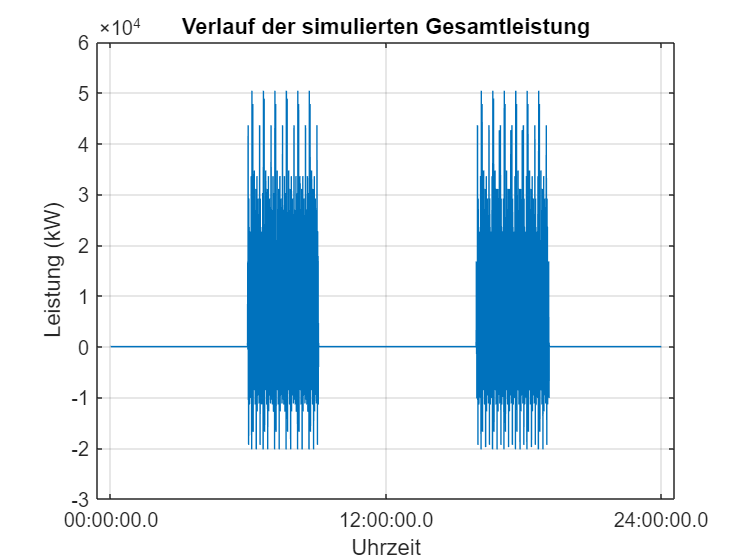

[P_totSim, CompleteData] = FahrplanSim(Timetable, SimStreckenU);

P_totSimBat.P_totSim = P_totSim; % (kW)
P_totDim.P_totSim = P_totSim; % (kW)


## Simulation mit vorgegebener Batterie: (SimBatFast, SimBatCont, SimBatPeak)

Bei dieser Berechnung sollen Batterieparameter vorgegeben werden. Aufgrund dieser Parameter sollen neue Strecken- und Tageslastprofile erstellt werden. Dies soll dabei helfen, die Auswirkungen einer bestimmten Batterie auf den Leistungsverlauf abzuschätzen.

Die Resultate der Batterieauswirkungen werden in verschiedenen Methoden berechnet und ausgegeben. Die 

- **Schnelles Entladen:** Batterie wird immer voll gebraucht. Es wird versucht von Beginn an so viel Leistung zu decken wie möglich.

- **Kontinuierlicher Ansatz**: Dabei wird eine kontinuierliche Leistung über den gesamten Verlauf gedeckt.

- **Peak-Shaving Ansatz:** Dabei wird versucht, die höchsten Leistungsspitzen abzudecken.

Bei allen Methoden kann angegeben werden ob die Berechnung mit oder ohne Laden der Batterie durchgeführt und ausgegeben werden soll.

Zudem werden zum Schluss die Resultate der verschiedenen Methoden analyisert und dargestellt.

% Es können mehrere Batterien miteinander getestet werden. Dafür müssen die
% Angaben für Leistung, Energie und Wirkungsgrad in einem Array angegeben
% werden. Bsp. für vier Batterien: Leistung = [10, 12, 14, 20] (Leistung in kW)

% mögliche Entladeleistung der Batterie
Leistung = [500,1000,1500,2000,3000]; % (kW)
%Leistung = 2000;

% mögliche Ladeleistung der Batterie
Ladeleistung = [500,1000,1000,2000,1500]; % (kW)
%Ladeleistung = 2000;

% Angabe der Batteriekapazität
Energie = [25,30,40,50,60]; % (kWh)
%Energie = 15;

% Angabe des Wirkungsgrades der Batterien
Wirkungsgrad = [95, 95, 95, 95, 95]; % (%)
%Wirkungsgrad = 95;

% Angabe ob die simulation mit oder ohne Laden der Batterie gemacht werden
% soll.
Recharge = "Y"; % (Y/N)

% Prozentsatz der Batteriebesetzten Fahrzeuge
BatShare = 100; % (%) 

% Mit nachfolgender Funktion wird die erste Methode (schnelles Entladen) berechnet.
if(input('Soll die Funktion für die erste Methode (schnelles Entladen) durchgeführt werden? (Y/N)','s') == "Y")
    [BatSpecFast, P_totSimBatFast] = SimBatFast5(Leistung, Ladeleistung, Energie, Wirkungsgrad, SimStreckenU, const, Recharge, Timetable, P_totSim, BatShare);
    P_totSimBat.P_totSimBatFast = P_totSimBatFast;
end

% Mit nachfolgender Funktion wird die zweite Methode (kontinuierlich) berechnet.
if(input('Soll die Funktion für die zweite Methode (kontinuierlich) durchgeführt werden? (Y/N)','s') == "Y")
    [BatSpecCont, P_totSimBatCont] = SimBatCont3(Leistung, Ladeleistung, Energie, Wirkungsgrad, SimStreckenU, const, Recharge, Timetable, P_totSim, BatShare);
    P_totSimBat.P_totSimBatCont = P_totSimBatCont;
end

% Mit nachfolgender Funktion wird die dritte Methode (Peak-Shaving) berechnet.
if(input('Soll die Funktion für die dritte Methode (Peak-Shaving) durchgeführt werden? (Y/N)','s') == "Y")
    [P_totSimBatPeak2, BatSpecPeak2] = SimBatPeak5(Leistung, Ladeleistung, Energie, Wirkungsgrad, SimStreckenU, const, Recharge, Timetable, P_totSim, BatShare);
    P_totSimBat.P_totSimBatPeak = P_totSimBatPeak;
end

% Analyse der Resultate:
if(input('Sollen die Resultate miteinander verglichen und dargestellt werden? (Y/N)', 's') == "Y")
    P_totSimMean = ResultsBatSpec(P_totSimBat, Meas, Leistung);
end


## Auslegung einer Traktionsbatterie: (CalcBatDimCont, CalcBatDimPeak)

In diesem Abschnitt soll für verschiedene Strecken eine optimale Traktionsbatterie ausgelegt werden. Die Berechnung soll die Batterieparameter so auslegen, damit die vorgegebenen Deckungsgrade erreicht werden können. Der Deckungsgrad wird hierbei so folgendermassen definiert: Der Deckungsgrad gibt an, welcher prozentuale Anteil der simulierten Fahrt (Leistung oder Energie) während der Fahrt gedeckt werden soll. Bei einem Deckungsgrad von z.Bsp. 10% soll im peak-shaving Ansatz 10% der während der Fahrt vom Triebfahrzeug vom Netz bezogenen Energie durch die Batterie gedeckt werden. Dabei werden zwei Ansätze für diese Berechnung analysiert:

- **Kontinuierliche Methode:** Bei der kontinuierlichen Methode soll während der gesamten Fahrt ein vorgegebener Anteil der vom Triebfahrzeug benötigten Leistung von der Batterie kommen. Dies bedeutet, dass wenn zum Zeitpunkt t1 bei einem Deckungsgrad von 10% eine Leistung von 2 MW benötigt wird, 200 kW von der Batterie kommen sollen. Wenn beim Zeitpunkt t2 dann 3.5 MW benötigt werden, sollen auch 10%, d.h. 350 kW von der Batterie zur Verfügung gestellt werden. Dies führt dazu, dass zu jedem Zeitpunkt der Fahrt auch 10% weniger Leistung vom Netz bezogen wird.

- **Peak-Shaving Methode:** Bei der Peak-Shaving Methode wird gezielt versucht, die Leistungsspitzen der simulierten Fahrt zu reduzieren. Durch den Deckungsgrad wird dabei vorgegeben, welchen Prozentsatz der während der gesamten Fahrt bezogenen Energie durch die Batterie abgedeckt werden soll. Bsp.: Deckungsgrad = 10%, benötigte Energie = 100 kWh, von der Batterie zu deckende Energie = 10 kWh. Diese Energie soll nun innerhalb der Leistungsspitzen der Fahrtsimulation abgedeckt werden. Das heisst, es wird ein Schwellenwert der Leistung bestimmt. Jegliche Leistung, welche höher ist als dieser Schwellenwert soll von der Batterie abgefangen werden und somit die Leistungsspitzen begrenzen.

Es kann wiederum gewählt werden, ob es möglich sein soll, dass die Batterie während der Fahrt geladen wird. Bei der kontinuierlichen Methode entspricht die Ladeleistung bei jedem Zeitpunkt auch dem vorgegebenen Deckungsgrad.

Das **Laden** mit der **Peak-Shaving** Methode kann jedoch unterschiedlich gemacht werden. In der Funktion wurden zwei mögliche Methoden für das Ladevorgehen beim Peak-Shaving implementiert. Diese werden nachfolgend kurz beschrieben:

- **Schnelles Laden**: Hierbei wird so viel geladen wie möglich. Begrenzt wird die Ladeleistung nur durch die vorher durch den Deckungsgrad bestimmte Entladeleistung.

- **Schnelles Laden mit Grenzwert**: Bei dieser Methode wird nur so lange geladen, bis die Batterie wieder einen SOC von 100% erreicht hat. Dies führt im Vergleich zur ersten Methode dazu, dass die benötigte Batteriekapazität durch das Laden der Batterie weiter erhöht wird.

- **Laden mit Begrenzung**: Wenn die benötigte Batteriekapazität so klein wie möglich gehalten werden soll, dann wird über den gesamten Verlauf nur so viel geladen, wie auch entladen wird. Dafür wird auch für die negative Seite ein Grenzwert gesucht.

Die Batterie soll bei den einzelnen Methoden so ausgelegt werden, dass die Bedingungen für den vorgegebenen Deckungsgrad erfüllt werden können. Für die Berechnungen können auch mehrere Deckungsgrade gleichzeitig vorgegeben werden. Dadurch können gleichzeitig für jeden Deckungsgrad eine Batterie ausgelegt werden.

Für die Berechnungen werden die im Abschnitt "Simulation aller Strecken mit allen Fahrtzeiten" simulierten Streckensimulationen benötigt.

% Angabe, welche Deckungsgrade ausgelegt werden sollen.
%CR = [10, 20, 50]; % (%) der max. Leistung bzw. der Energie
CR = [1, 2, 5, 10, 15, 20, 25, 30, 40, 50, 60];
%CR = 10;

% Angabe des Wirkungsgrades der Batterie
Wirkungsgrad = 95; % (%)

% Angabe ob es erlaubt sein soll, während der Fahrt die Batterie zu laden
% Dies wird in jedem Fall berechnet, hier wird nur angegeben, welcher
% Verlauf dargestellt werden soll.
Recharge = "N"; % (Y/N)

% Prozentsatz der Batteriebesetzten Fahrzeuge
BatShare = 100; % (%) 

% Berechnung und Auslegung der Batterie mit der kontinuierlichen Methode
if(input('Soll die kontinuierliche Auslegung der Batterie durchgeführt werden? (Y/N)', 's') == "Y")
    [BatDimCont, BatDimParametersCont, P_totSimBatDimCont] = CalcBatDimCont2(SimStreckenU, P_totSim, CR, const, Timetable, Wirkungsgrad, Recharge, BatShare);
    P_totDim.P_totSimBatDimCont = P_totSimBatDimCont;
end

% Entscheidung welche der oben beschriebenen Lademethoden durchgeführt werden soll.
ChargeMethod = 3; 

% Berechnung und Auslegung der Batterie mit der Peak-Shaving Methode
% (Methode 1, 2 oder 3 für das Laden)
if(input('Soll die Peak-Shaving Auslegung der Batterie durchgeführt werden? (Y/N)', 's') == "Y")
    [BatDimPeakM3, BatDimParametersPeakM3, P_totSimBatDimPeakM3] = CalcBatDimPeak4(SimStreckenU, P_totSim, CR, const, Timetable, Wirkungsgrad, Recharge, BatShare, ChargeMethod);
    P_totDim.P_totSimBatDimPeakM3 = P_totSimBatDimPeakM3;
end


% Darstellung der Resultate (Kontinuierlich und Peak-Shaving)
if(input('Sollen die Resultate aus der Auslegung der Batterie dargestellt werden? (Y/N)', 's') == "Y")
    P_totDimMean = ResultsBatDim(P_totDim, Meas, CR, BatDimParametersCont, BatDimParametersPeak);   
end


## Auslegung Traktionsbatterie für gesamte Fahrt: (CalcBatDimTot)

Im folgenden Abschnitt soll eine Batterie ausgelegt werden, mit welcher man die jeweilige Fahrt komplett ohne Fahrleitung erreichen sollte. Dies bedeutet, dass die Batterie so ausgelegt wird, dass die gesamte Fahrt Batteriebetrieben zurückgelegt werden könnte.

% Wirkungsgrad der Batterie 
Wirkungsgrad = 95; % (%)

%Prozentsatz der Batteriebesetzten Fahrzeuge
BatShare = [20, 50, 100]; % (%) 

% Auslegung von Batterieparametern und Simulation der Strecken und
% Gesamtleistung
[BatDimTot, BatDimParametersTot, P_totSimBatDimTot] = CalcBatDimTot(SimStreckenU, BatShare, Timetable, Wirkungsgrad, P_totSim, Meas, const);


## Auslegung Traktionsbatterie für Fahrt mit konstanter Leistung: (CalcBatDimCont)

Ein weiterer Ansatz um die Lastspitzen im Netz zu reduzieren ist, die Batterien so einzusetzen, dass zu jedem Zeitpunkt eine konstante Leistung vom Zug bezogen wird. Dies kann nicht nur die Leistungsspitzen im Netz senken, sondern ermöglicht die einfache prognostizierbarkeit von Lastflüssen, da jedes Fahrzeug über jeden Streckenabschnitt eine im vorhinein bekannten Leistungsbezug aufweist.

Für die Berechnung muss die maximale Grenzlast, welche der Zug maximal vom Netz beziehen soll, angegeben werden. Es können auch mehrere Grenzwerte angegeben werden, welche dann gleichzeitig berechnet werden.

Es folgt eine kurze Beschreibung der Fälle für den Einsatz der Batterie die während der Fahrt auftreten können:

-  Fall: Zug bezieht Leistung vom Netz aber weniger als der im vorhinein bestimmte Grenzwert (Threshold). In diesem Fall wird mit dem Unterschied zwischen Grenzwert und der simulierten Leistung die Batterie geladen. Bsp: PThresh = 2 MW, P_sim = 1.3 MW, P_laden = PThresh - P_sim = 0.7 MW

- Fall: Zug bezieht Leistung vom Netz, welche höher ist als der Grenzwert. In diesem Fall kommt die Differenz zwischen Grenzwert und sim. Leistung von der Batterie. Bsp: PThresh = 2 MW, P_sim = 3.2 MW, P_entladen = P_sim - PThresh = 1.2 MW

- Fall: Benötigte Zugleistung ist negativ (Bsp. bei Bergabfahrt) und Leistung könnte ins Netz gespiesen werden. Hier werden zwei Varianten betrachtet:

- 3.1. Da eine konstante Leistung gewünscht wird, muss hier trotzdem Leistung aus dem Netz bezogen werden. Die Batterie wird also geladen und zwar mit der negativen Leistung bis zu Leistung = 0 sowie Leistung aus dem Netz bis zum Schwellwert. Bsp: P_thresh = 2 MW, P_sim = -1.5 MW, P_laden = P_thresh - P_sim = 3.5 MW

- 3.2. Hier wird die Batterie geladen. Ziel ist es, dass eine Leistung von 0 anliegt. Es wird also nur die negative Leistung in die Batterie gespeichert. Bsp: P_thresh = 2 MW, P_sim = -1.5 MW, P_laden = 1.5 MW, P_tot = 0 MW

Es kann vor der Berechnung ausgesucht werden, welche Methode bei einer negativen Leistung verwendet werden soll. Entweder wird bei einer negativen Leistung die Batterie geladen damit ebenfalls der Threshold vom Netz bezogen wird oder sie wird so geladen, dass keine Leistung mit dem Netz ausgetauscht wird.

% Die zu begrenzende Leistung kann nachfolgend vorgegeben werden (kW) Bsp: 1000, [1000; 2000]:
PThresh = [1000;2000;3000]; % (kW)

% Thresh = Grenzwert immer einhalten, Null = bei negativer Leistung
Methode = "Null"; 

% gewünschter Wirkungsgrad der Batterie
Wirkungsgrad = 95; % (%) 

% Anteil der Batteriebesetzten Fahrzeuge:
BatShare = 100; % (%)

% Funktion um die Batterie für konstante Leistung auszulegen.
[BatDimConst, BatDimParametersConst, P_totSimBatDimConst] = CalcBatDimConst(SimStreckenU, P_totSim, PThresh, Methode, const, Wirkungsgrad, Timetable, BatShare, Meas);


## Modulauslegung für ausgelegte Traktionsbatterien

Mit dieser Funktion können, mit Hilfe von hinterlegten Parametern von Batteriemodulen, die benötigte Anzahl und Anordnung von Modulen für die mit der Peak-Shaving und Kontinuierlichen Methode ausgelegten Traktionsbatterien bestimmt werden. 

% Für die Modulauslegung muss ein Batteriemodul vorgegeben werden. Bereits
% hinterlegt ist das Modul Bordline von ABB. Weitere Module können im
% Skript "BatterieModul.mlx" hinterlegt werden.

% Laden der hinterlegten Batteriemodule:
BatterieModul;

% Bestimmung des Batteriemodules für die Auslegung:
Module = Bordline;

% Ausführung der Modulauslegung
[ModuleCont, ModulePeakM3] = CalcModuleCompositionV2(BatDimParameters, Strecken, CR, Module);
